clc
clear
clear all

% Define system parameters
mc = 1.5;  % mass of the cart (kg)
mp = 0.5;  % mass of the pendulum (kg)
L = 1;     % length of the pendulum (m)
g = 9.82;  % gravity (m/s^2)
d1 = 0.01; % damping coefficient for the cart
d2 = 0.01; % damping coefficient for the pendulum
g_q=[1;0];

## Define the matrices

A = [0,0,1,0;
    0,0,0,1;
    0, (g*mp)/mc,-d1/mc,-d2/(L*mc);
    0, (g*(mc+mp))/(L*mc), -d1/(L*mc), -(d2*mc + d2*mp)/(L^2*mp*mc)];

B=[0 ; 0 ; 1/mc ; 1/(L*mc)];
% C = [0;1;0;0]; % q_2 as the output
C = [1;0;0;0]; % q_1 as the output
D =0;

## Built the system

sys = ss(A,B,C',D)


sys =
 
  A = 
              x1         x2         x3         x4
   x1          0          0          1          0
   x2          0          0          0          1
   x3          0      3.273  -0.006667  -0.006667
   x4          0      13.09  -0.006667   -0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


eig(A) % or the pole of the system

ans =          0
   -3.6327
    3.6043
   -0.0050


Sc= ctrb(sys)

Sc =          0    0.6667   -0.0089    2.1824
         0    0.6667   -0.0222    8.7295
    0.6667   -0.0089    2.1824   -0.1455
    0.6667   -0.0222    8.7295   -0.5383


rank(Sc)

ans = 4

So = obsv(sys)

So =     1.0000         0         0         0
         0         0    1.0000         0
         0    3.2733   -0.0067   -0.0067
         0   -0.1091    0.0001    3.2736


rank(So)

ans = 4

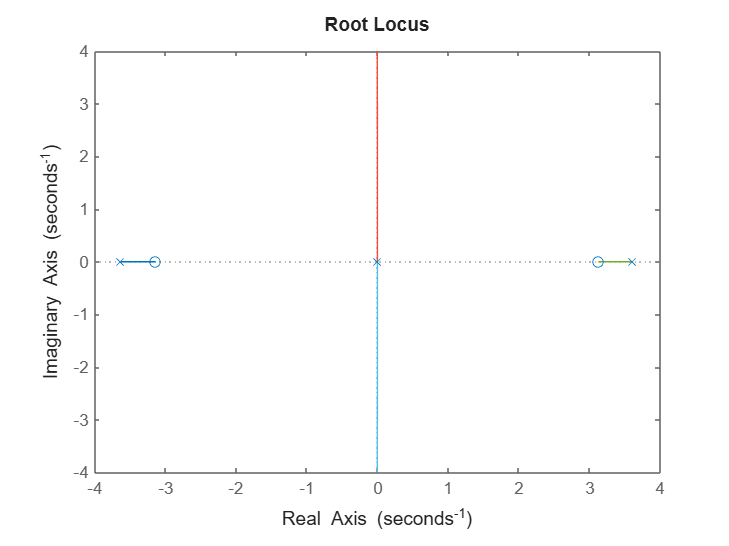

rlocus(sys);

## Initial Condition

x0=[0; 5*pi/180 ; 0 ; 0];


## Bulid COntrollor

des_pole=[-3;-3;-3;-3]*1;
K = acker(A,B,des_pole)

K =   -12.3727  113.3432  -16.5321   34.4821


Q= eye(4);
R=0.1;
K_lqr=lqr(A,B,Q,R)

K_lqr =    -3.1623   72.7343   -6.6580   21.7182


## Discretise the signal

Ts=0.1

Ts = 0.1000

sys_d= c2d(sys,Ts)


sys_d =
 
  A = 
               x1          x2          x3          x4
   x1           1     0.01653     0.09997    0.000515
   x2           0       1.066  -3.366e-05      0.1021
   x3           0       0.334      0.9993     0.01585
   x4           0       1.336  -0.0006802       1.063
 
  B = 
             u1
   x1  0.003341
   x2  0.003366
   x3   0.06699
   x4   0.06802
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.


Ad=sys_d.a;
Bd=sys_d.b;
Cd=sys_d.c;
Dd=sys_d.d;




## Controllor & observer design

Q= 300*diag([1,10,1,1]);
R=0.02;
N=zeros(length(B),1);

[K_d,~,~] = dlqr(Ad,Bd,Q,R,N);
[Ob,~,~] = dlqr(Ad',Cd',Q,R,N);